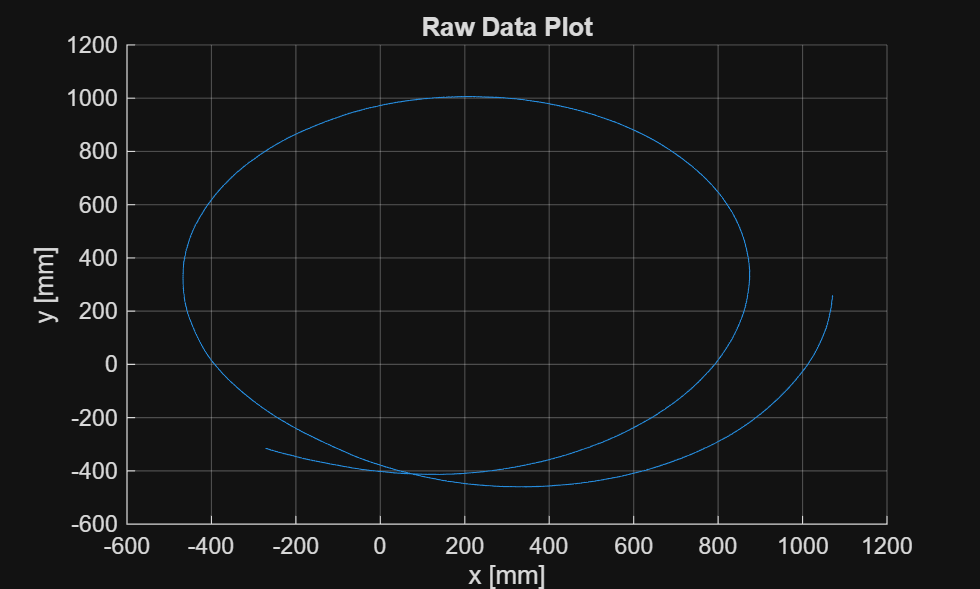

%#ok<*CLALL>

clear all;clc 


% Load data set data_20250902_1358_0.30L_0.15R
data = readtable('data/data_20250902_1358_0.30L_0.15R.csv', 'NumHeaderLines', 1);
data = table2array(data);

% Plot raw data. 
clf(); 
hold on; 
plot(data(:, 2), data(:, 3));
xlabel('x [mm]');
ylabel('y [mm]');
title('Raw Data Plot');
grid on;
hold off; 

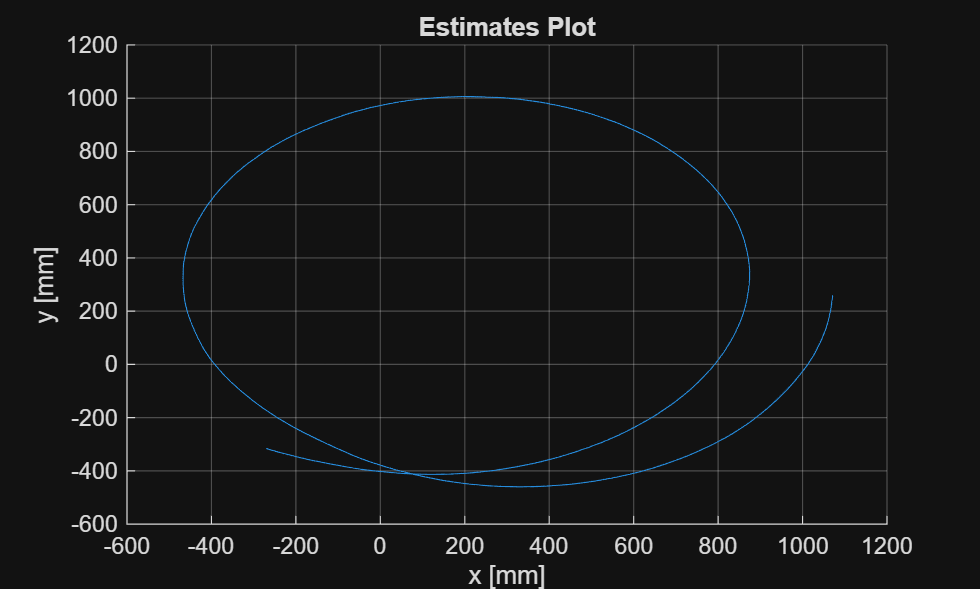

% Test run the extended Kalman Filter. 
u = [0.30; 0.15]; 
Q = [ ...
    1 0 0; ...
    0 1 0; ...
    0 0 1]; 
R = [ ...
    1 0; ...
    0 1]; 
x_0 = [data(1, 2:3).'; 3*pi/2]; 
ekf = lab1EKF(x_0, Q, R); 
estimates = zeros(size(data, 1), 3); 
for k = 1:size(data, 1)
% for k = 1:16
    z = data(k, 2:3).'; 
    estimates(k, :) = ekf.update(u, z);
end

% Plot estimates. 
clf(); 
hold on; 
plot(estimates(:, 1), estimates(:, 2));
xlabel('x [mm]');
ylabel('y [mm]');
title('Estimates Plot');
grid on;
hold off; 